# Repàs de la segmentació per watershed

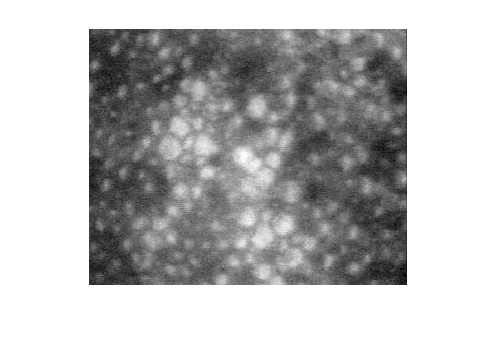

%obrir l'imatge cornea.tif
orig = imread("cornea.tif");
imshow(orig);

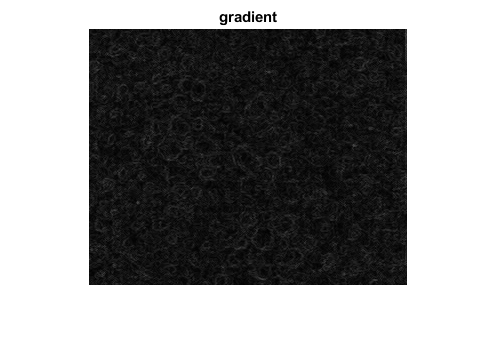


%element estructurant disk de radi 1:
ee = strel('disk', 1);

% calculem el gradient. Ho podem fer morfològic
grad = imsubtract(imdilate(orig, ee), imerode(orig, ee));
figure,imshow(grad),title('gradient')

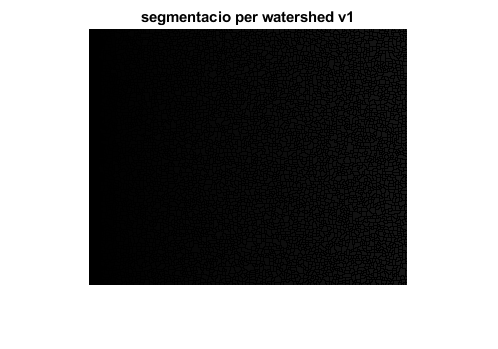


segm=watershed(grad);
figure, imshow(segm), title('segmentacio per watershed v1')

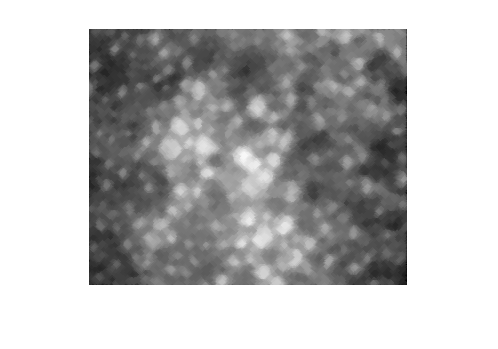

%sobresegmentat, cal treball amb markers:

%%MARKER-CONTROLLED WATERSHED
ee = strel('disk', 2);
filt=imopen(imclose(orig,ee),ee); %filtrem primer, la imatge es molt sorollosa.
figure,imshow(filt)

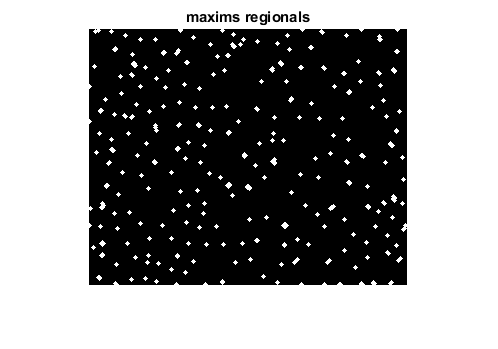

% Usem els maxims regionals com a markers pel watershed
rm=imregionalmax(filt);
figure,imshow(rm),title('maxims regionals')

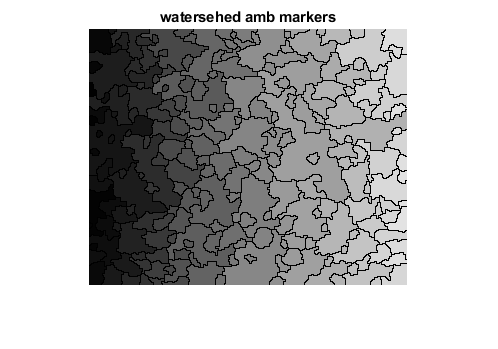

segm=watershed(imimposemin(grad,rm));
figure,imshow(segm),title('watersehed amb markers') 

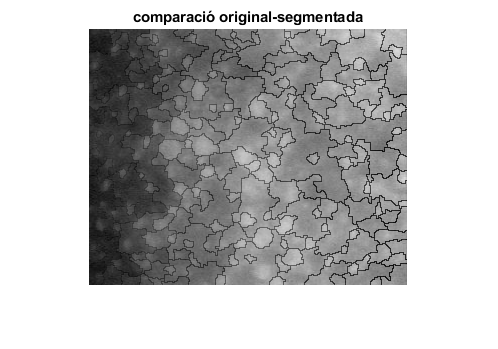


over = imfuse(orig, segm, 'blend');
figure, imshow(over), title('comparació original-segmentada')

%- La crida imfuse permet crear una imatge composta de dos imatges, 
% el paràmetre 'blend' superposa una imatge sobre l'altra i "juga" amb la 
% transparència d'una sobre l'altra.
%

**Us sembla correcta la segmentació? O ens em oblidat alguna cosa ?**

La segmentació no sembla la mes correcta, tenim sobresegmentació perque ens em oblidat de donar una marca al "fons".

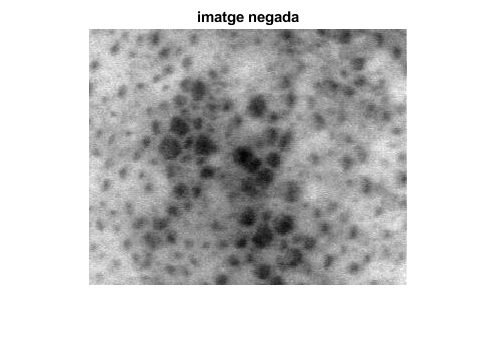


%% Cal trobar un marker pel fons
% L'obtenim fent el watershed de la imatge negada.
%Usem com a markers els mateixos maxims d'abans
Norig=imcomplement(orig);
figure,imshow(Norig),title('imatge negada')

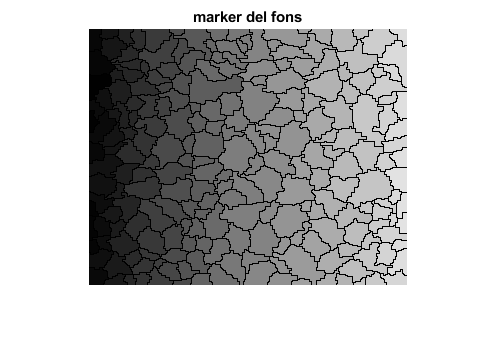

fons=watershed(imimposemin(Norig,rm));
figure,imshow(fons),title('marker del fons')

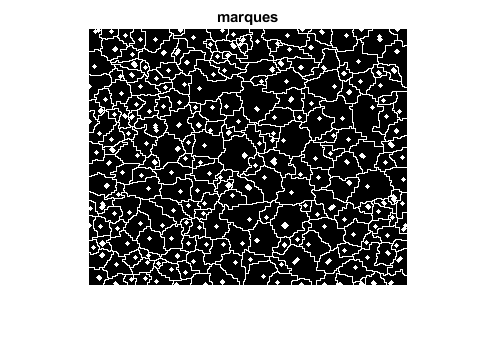

% Fem una imatge de markers a partir de les celules i del fons
markers=~fons|rm;
figure,imshow(markers),title('marques')

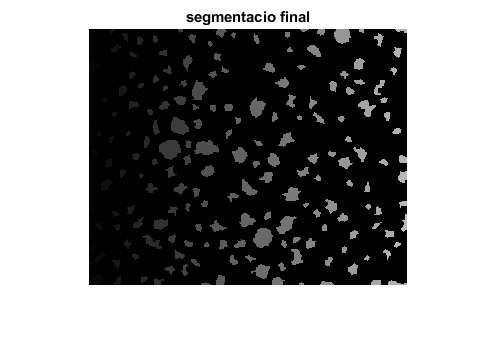

% fem el watershed amb les noves marques
segm=watershed(imimposemin(grad,markers));
figure,imshow(segm),title('segmentacio final')

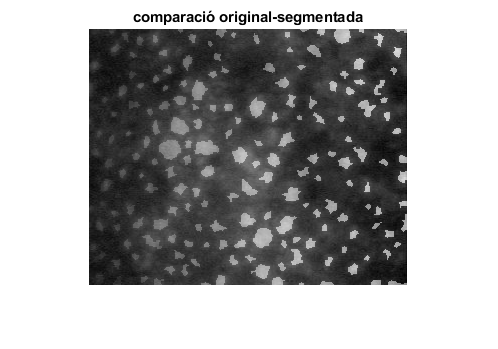


%Dibuixeu de nou  el resultat en overlay
over = imfuse(orig, segm, 'blend');
figure, imshow(over), title('comparació original-segmentada')

**Utilitzeu operacions morfològiques sobre les imatges de marques per a evitar que els markers es toquin. Genereu una nova imatge de marques.**

**Segmenteu la imatge amb watershed usant les noves marques i mostreu el resultat en overlay.Utilitzeu operacions morfològiques sobre les imatges de marques per a evitar que els markers es toquin. Genereu una nova imatge de marques.**

**Segmenteu la imatge amb watershed usant les noves marques i mostreu el resultat en overlay.**

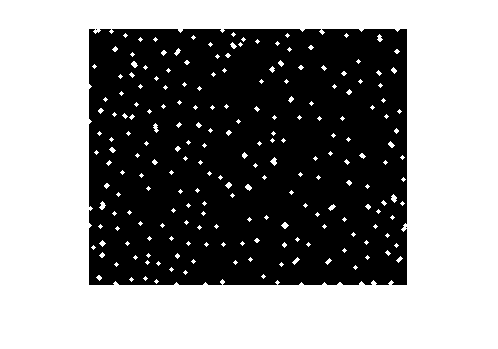

imshow(rm); %marques originals local, les que es toquen s'han de separar.

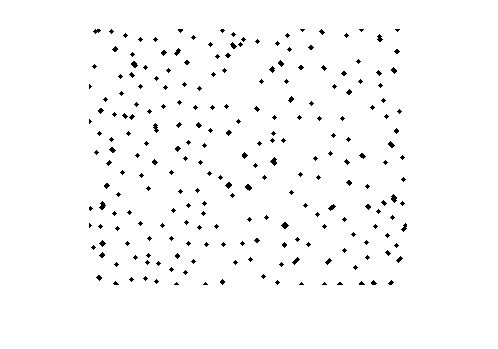

D = bwdist(~rm);
D = imcomplement(D);
imshow(D);

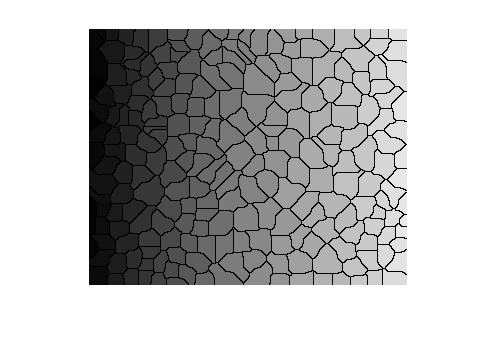

L = watershed(D); L(~rm);
imshow(L);

%markers2 = fons|L;
%segm2 = watershed(imimposemin(grad,markers));
%figure,imshow(segm2),title('segmentacio final')
%over2 = imfuse(orig, segm2, 'blend');
%figure, imshow(over2), title('comparació original-segmentada')

He intentat aplicar la transformada de la distància per separar els punts, però no he sabut continuar.  